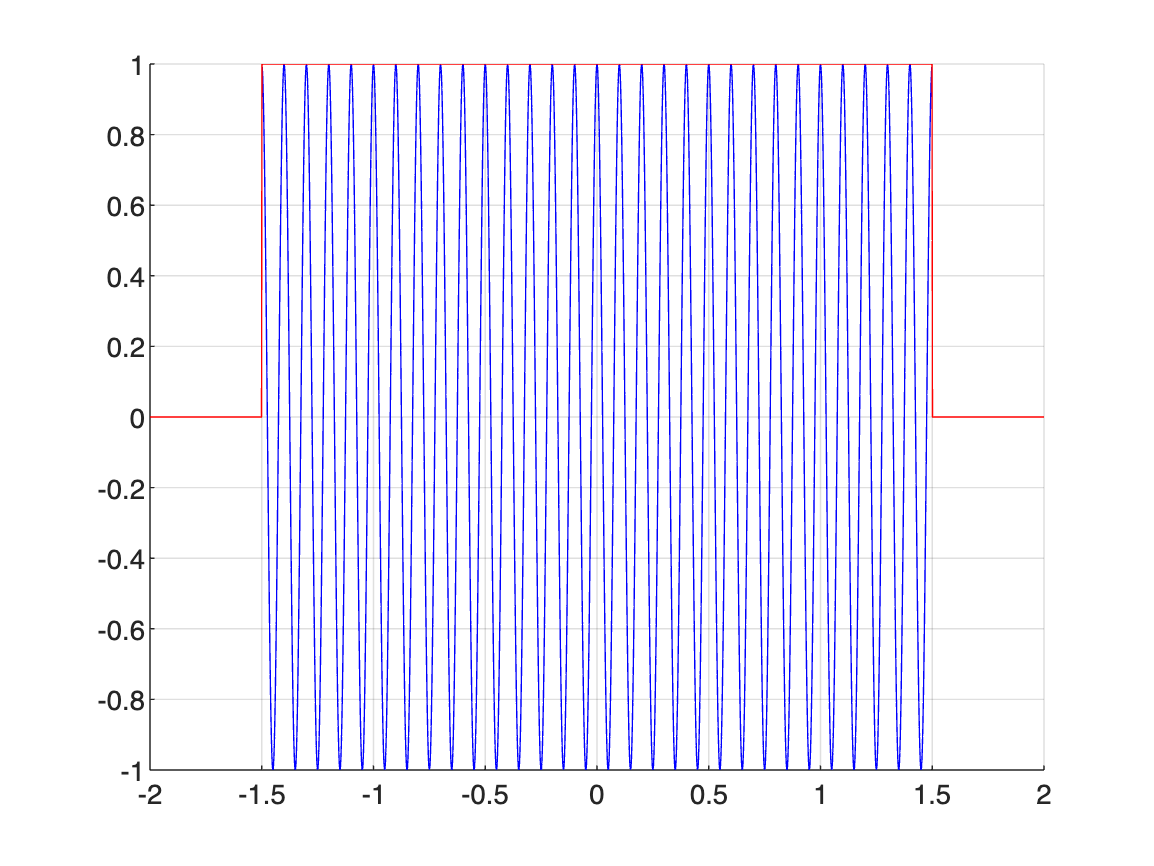

clf
fc = 10;
T = 3;
B = 2;
A = 1;

t = -2:0.001:2;
x = A * rectangularPulse(-T/2, T/2, t) .* cos(2*pi*fc*t);
h = A * rectangularPulse(-T/2, T/2, t);

hold on
plot(t, x, "b")
plot(t, h, "r")
grid on 

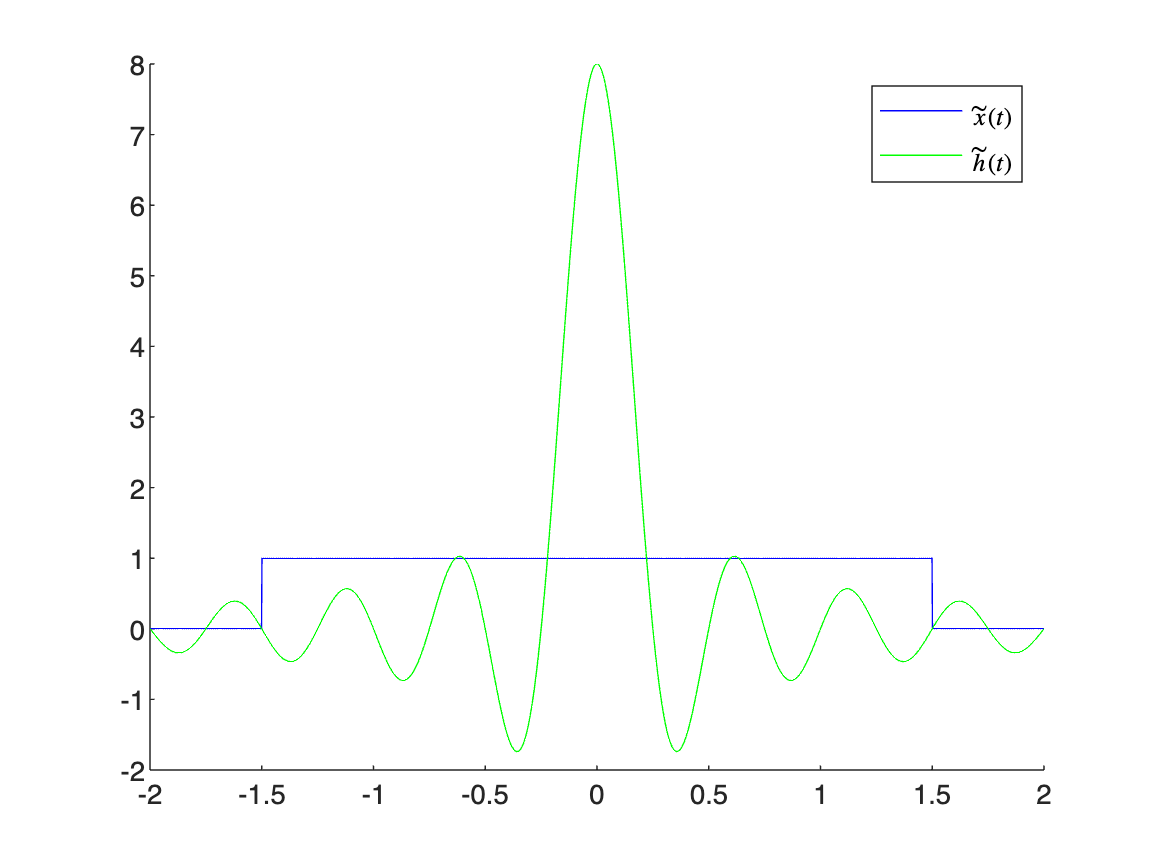

clf
h_tilde = 4 * B * sinc(2*B*t);
x_tilde = A * rectangularPulse(-T/2, T/2, t);
hold on
plot(t, x_tilde, "b")
plot(t, h_tilde, "g")
legend('$\tilde{x}(t)$', '$\tilde{h}(t)$', 'Interpreter', 'latex')

clf
y_tilde = conv(h_tilde, x_tilde);
y_tilde = y_tilde(2000:6000);

y_tilde = 1.0e+03 *

    0.0719    0.0719    0.0719    0.0719    0.0719    0.0718    0.0717    0.0716    0.0715    0.0714    0.0713    0.0711    0.0709    0.0708    0.0706    0.0703    0.0701    0.0698    0.0696    0.0693    0.0690    0.0687    0.0683    0.0680    0.0676    0.0672    0.0668    0.0664    0.0659    0.0655    0.0650    0.0645    0.0640    0.0635    0.0629    0.0624    0.0618    0.0612    0.0606    0.0600    0.0593    0.0587    0.0580    0.0573    0.0566    0.0559    0.0551    0.0544    0.0536    0.0528


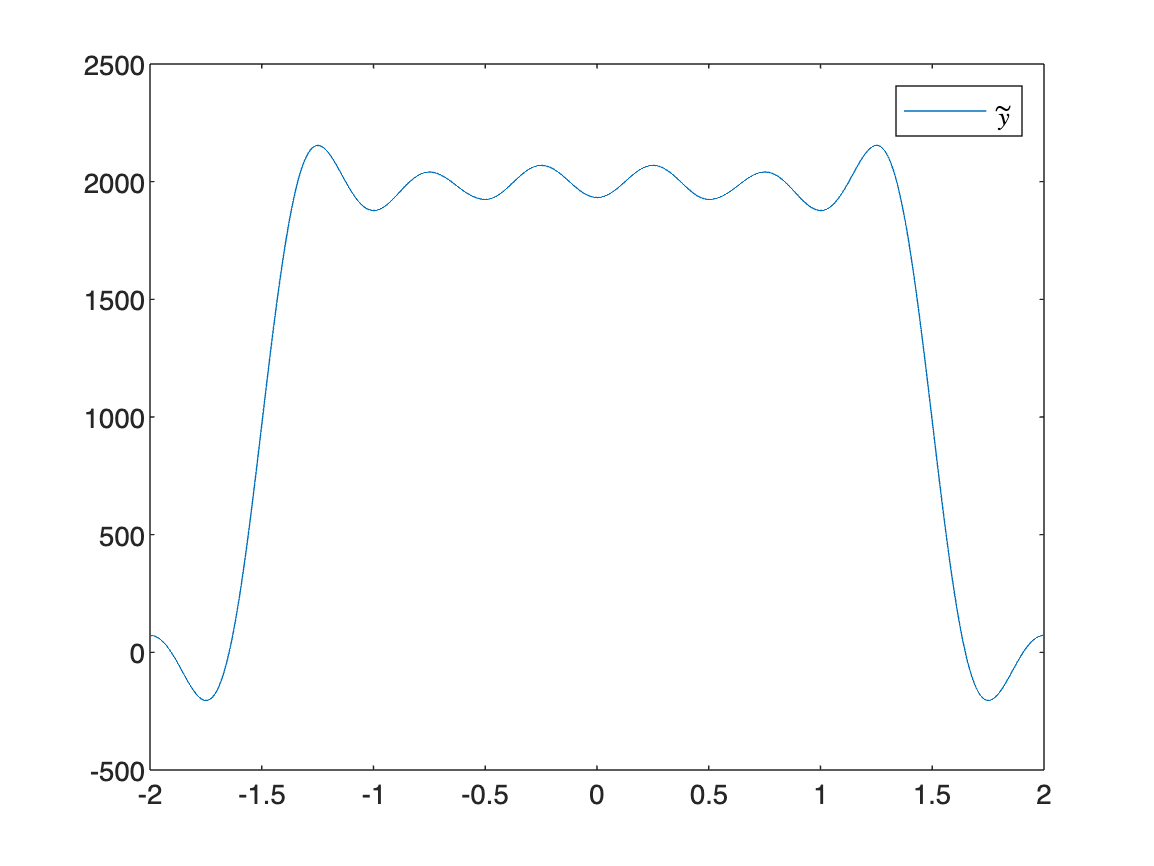

plot(t, y_tilde)
legend('$\tilde{y}$', 'Interpreter', 'latex')

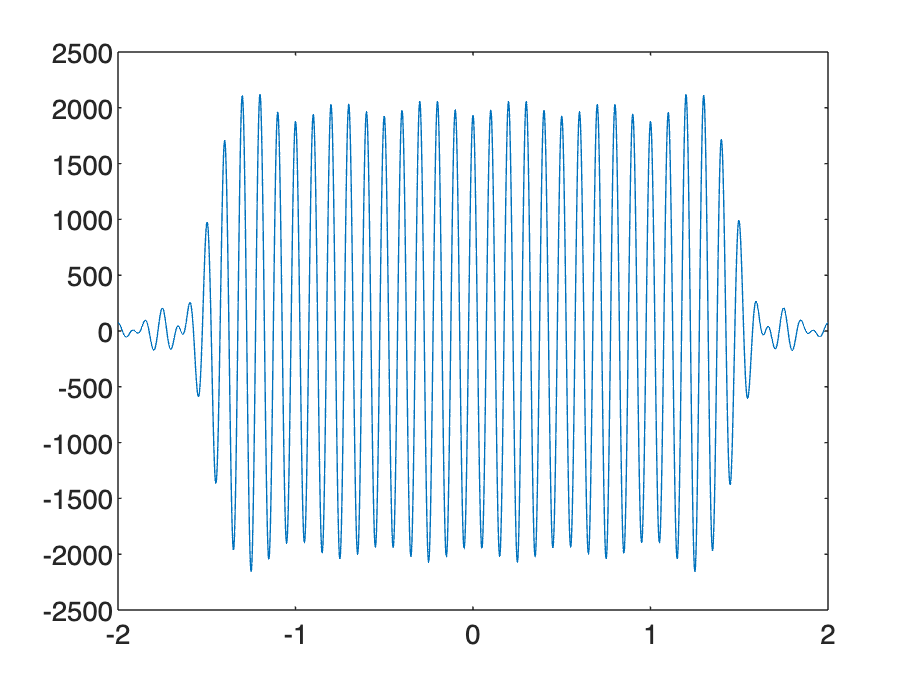

clf
y = real(y_tilde.*exp(1j*2*pi*fc*t));
plot(t, y)